% This file is used to solve Task 4B.
% It also makes use of a self-defined function named "SimilarReviews". 
% SimilarReviews performs the comparison of finding the top 10 similar
% reviews for each of the queries in "JewelleryReviewsQueries.csv"

% Creating a filename for the queries csv for loading and usage
filename = "JewelleryReviewsQueries.csv";

% This loads the Queries from  "JewelleryReviewsQueries.csv" 
% As there are no headers in the CSV it is important to
% Set the ReadVariableNames property to false so the first line is not used
% as the header names
data_queries = readtable(filename,'TextType', 'string','ReadVariableNames',false);
 
% This gets all the text of the queries by accessing the data_queries table
queries = data_queries.Var2

queries = 8×1 string array
    "The ring is a great gift. My friend loves it"
    "horrible bad quality bracelet"
    "arrived promptly and happy with the seller"
    "wear it with casual wear"
    "i expected better quality. i will return this item"
    "looks beautiful. The design is pretty. pefect and color is light"
    "This ring looks nothing like the picture. the diamonds are small and not very noticeable"
    "braclet looked just like its picture and is nice quality sterling silver."


% This loads the lsaModel which was saved to the lsaModel.mat file in task
% 4A. This model will be used for finding the similar reviews to each
% query. 
load("lsaModel.mat","mdl_LSA");

% This creates a bag of words for the pre-processed queries. This is needed
% because the preprocesstext function needs an initial bag to compare the
% statistics as each step is completed. These values are not required for
% this task, and as a result, the output is supressed
bag_for_function = bagOfWords(tokenizedDocument(queries));


% This pre-processes the queries in the same way that the reviews were
% pre-processed. By inspection none of the queries are empty so there is no
% need to check for any missing rows. 
queries = preprocessText(queries,bag_for_function);

terms_2 = 55

number_of_terms_removed_by2 = 0

terms_3 = 55

number_of_terms_removed_by3 = 0

terms_4 = 39

number_of_terms_removed_by_4 = 16

terms_5 = 38

number_of_terms_removed_by5 = 1

terms_6 = 37

number_of_terms_removed_by6 = 1

terms_7 = 37

number_of_terms_removed_by7 = 0

terms_8 = 37

number_of_terms_removed_by8 = 0

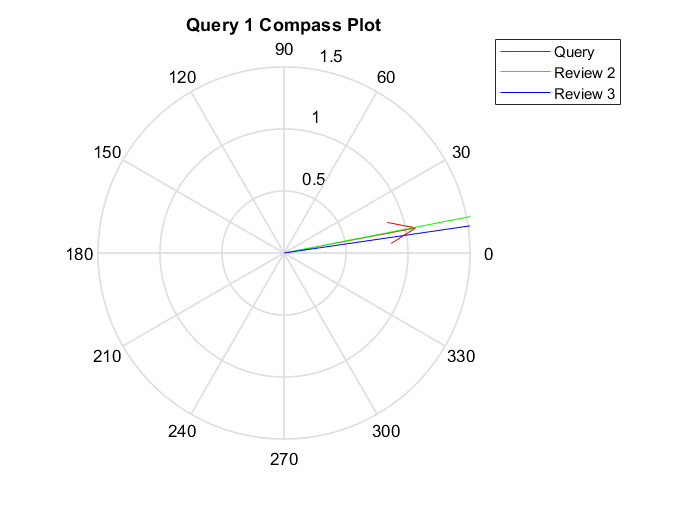

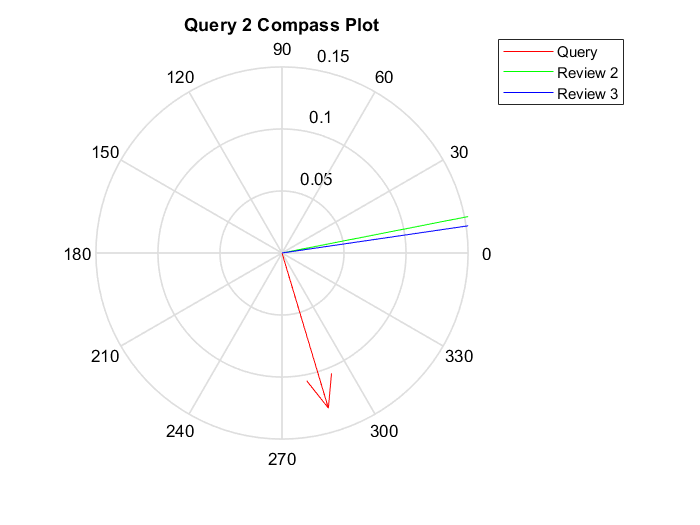

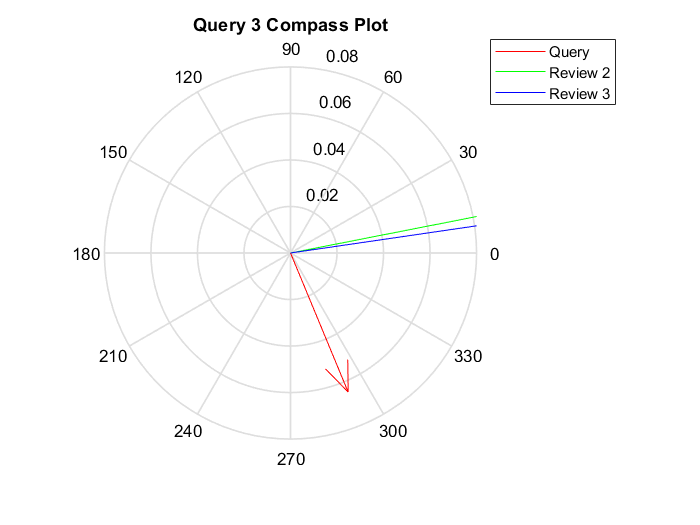

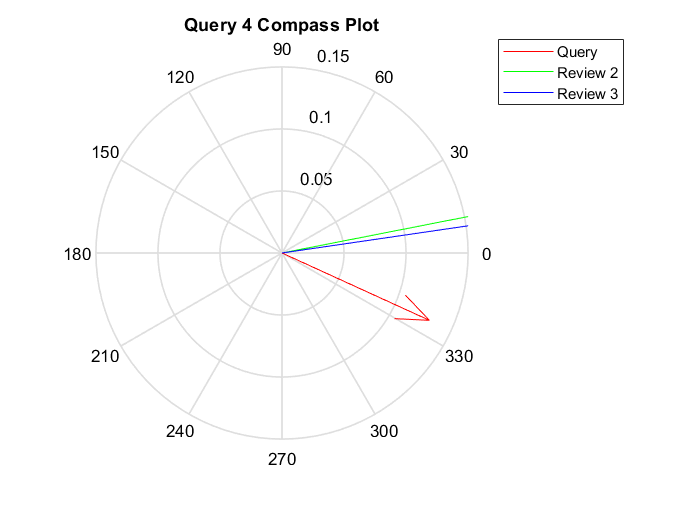

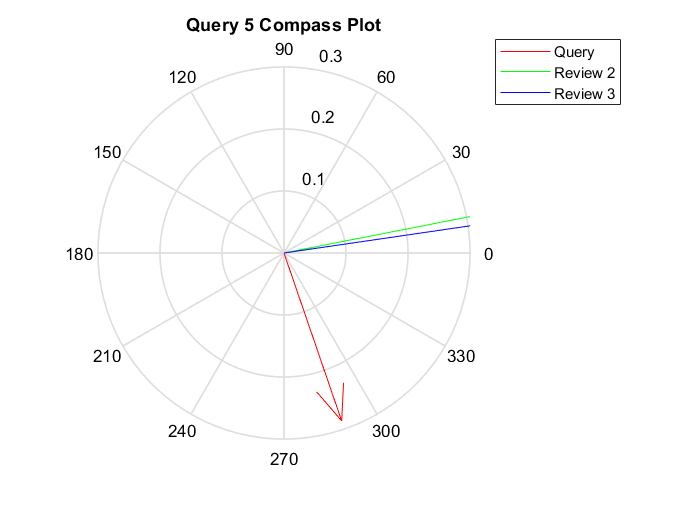

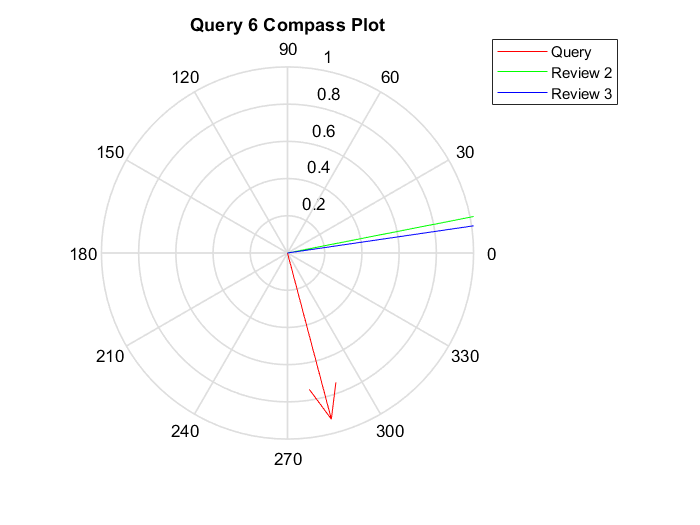

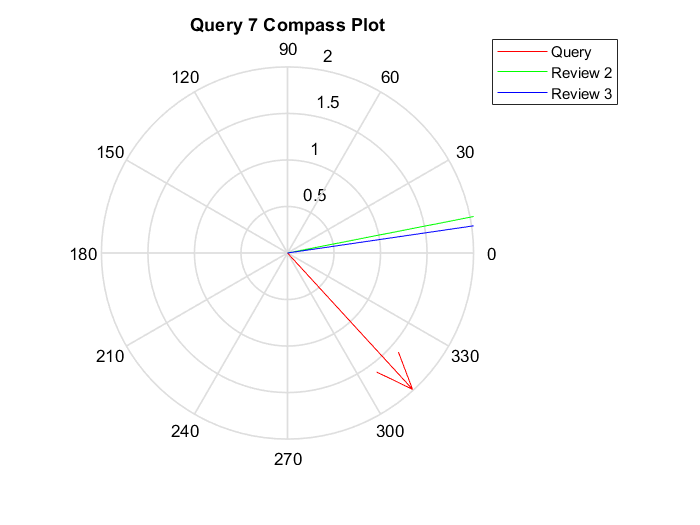

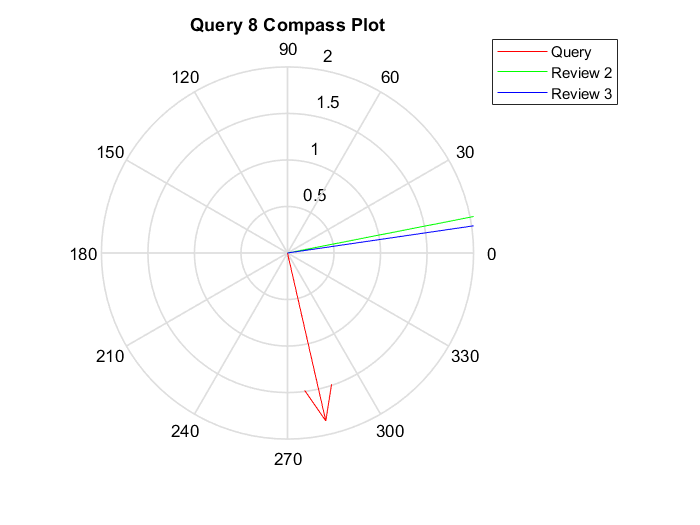


% Loop through the queries. Transform them, append them to the document
% scores of the LSA  model. Find the most similar ones. Sort and return top
% 10. 

% Creating 3 empty matrices which are 10 rows by 8 columns. Each matrix
% will hold the most similar documents to the queries using the specified
% distance metric. I.E the "ReviewsMatrix_Cosine" holds the most similar
% reviews for each query using cosine as the distance metric. The first
% column of each matrix contains the ID's of the most similar review for
% the first query, and so on for each column. 
ReviewsMatrix_Cosine = zeros(10,8);
ReviewsMatrix_Jaccard = zeros(10,8);
ReviewsMatrix_Euclidean= zeros(10,8);

% This loops over each query
for i = 1: length(queries)
    % This calls the self defined Similarreviews function which returns the
    % reviews (sorted by similarity) to the query in question using
    % "cosine" as the distance metric
    [reviews_for_query_cosine,scores] = Similarreviews(queries(i),mdl_LSA,"cosine");
    
    % This calls the self defined Similarreviews function which returns the
    % reviews (sorted by similarity) to the query in question using
    % "Jaccard" as the distance metric
    [reviews_for_query_Jaccard,scores] = Similarreviews(queries(i),mdl_LSA,"jaccard");
    
    % This calls the self defined Similarreviews function which returns the
    % reviews (sorted by similarity) to the query in question using
    % "euclidian" as the distance metric
    [reviews_for_query_Euclidean,scores] = Similarreviews(queries(i),mdl_LSA,"euclidean");
    
    % This inserts the top 10 most similar reviews associated with query i
    % to the correspoding reviews matrix. 
    ReviewsMatrix_Cosine(:,i) = reviews_for_query_cosine;
    ReviewsMatrix_Jaccard(:,i) = reviews_for_query_Jaccard;
    ReviewsMatrix_Euclidean(:,i) = reviews_for_query_Euclidean;
    
    % the scores vector contains the transformed scores for the query and reviews into
    % the model reduced vector space. A few of These are plotted to gain an
    % understanding of the similarities
    figure
    compass(scores(end,1),scores(end,2),'red')
    hold on
    compass(scores(2,1),scores(2,2),'green')
    compass(scores(3,1),scores(3,2),'blue')
    title("Query " + {i} +" Compass Plot")
    legend(["Query", "Review 2","Review 3"],'Location','bestoutside')
  
end


% The next 3 lines displays the most similar reviews to each query as a
% table. 
cosine_table = array2table(ReviewsMatrix_Cosine,...
'VariableNames',{'Query 1','Query 2','Query 3','Query 4','Query 5','Query 6','Query 7','Query 8'})

cosine_table = 10×8 table
    Query 1    Query 2    Query 3    Query 4    Query 5    Query 6    Query 7    Query 8
    _______    _______    _______    _______    _______    _______    _______    _______

     41876      55017      33251      53660      17607      46500        209        642 
     56494      25299      22058      30640      27679      10612      36165       3494 
     58481       7432       2780      28648      33571      41319      47345      37794 
     45278       2114       9726      37486      51907      27474        216      44490 
     35694      40871      26246      44126      32674      43945       7110      44489 
     34523      57123      13373      26535       1816      45860        943  

jaccard_table = array2table(ReviewsMatrix_Jaccard,...
'VariableNames',{'Query 1','Query 2','Query 3','Query 4','Query 5','Query 6','Query 7','Query 8'})

jaccard_table = 10×8 table
    Query 1    Query 2    Query 3    Query 4    Query 5    Query 6    Query 7    Query 8
    _______    _______    _______    _______    _______    _______    _______    _______

     32767      32767      32767      32767      32767      32767      32767      32767 
     15959      15959      15959      15959      15959      15959      15959      15959 
     43515      43515      43515      43515      43515      43515      43515      43515 
     46347      46347      46347      46347      46347      46347      46347      46347 
     30720      30720      30720      30720      30720      30720      30720      30720 
      1816       1816       1816       1816       1816       1816       1816 

Euclidean_table = array2table(ReviewsMatrix_Euclidean,...
'VariableNames',{'Query 1','Query 2','Query 3','Query 4','Query 5','Query 6','Query 7','Query 8'})

Euclidean_table = 10×8 table
    Query 1    Query 2    Query 3    Query 4    Query 5    Query 6    Query 7    Query 8
    _______    _______    _______    _______    _______    _______    _______    _______

     41876      32674      19852      53660      32674       3865        209        642 
     11247      19852       3494      19852      19852       3494       3494       3494 
     26246       3494      22058       2134      27679      41319      47345      10642 
     56494       1816       3865      37486       1816      52375      10642      45518 
     58481       3865      26246      26535      13373      19852      45518      44490 
     35694      19944      19944      44126      45548       1816      2854


% Saving the tables so they can be loaded and used in subsequent tasks 
save("reviewTables.mat","cosine_table","jaccard_table","Euclidean_table")

